clear;
addpath('./lib')
path = './data/';
files = strcat(path, {'2024-01-27-171211-SYSID.csv', '2024-01-27-171456-SYSID.csv', '2024-01-27-171637-SYSID.csv', '2024-01-27-172038-SYSID-TO-USE.csv', '2024-01-27-173926-SYSID-TO-USE.csv'});
raw = cell(size(files));
for i = 1:length(raw)
    data = readmatrix(files{i});
    data = data(1:end-1, :);
    % data = medfilt1(data,0,'truncate');
    raw{i} = data;
end
% raw{:} = raw{:}(1:end-1, :);

close all;
i = 4;
segments = raw{i}(:, 1);
time = raw{i}(:, 2);
throttle = raw{i}(:, 3);
alpha = raw{i}(:, 4);
force = raw{i}(:, 5);
torque = raw{i}(:, 6);
rpm = fillRPM(raw{i}(:, 7));

figure();
subplot(2, 1, 1);
plot(time, throttle);
% hold on
subplot(2, 1, 2);
plot(time, force);
% hold off

% return;





u = [throttle alpha];
y = [force torque rpm];
nx = 4;
Ts = mean(gradient(time));



% 
% sys = ssest(u, y, nx, 'Ts', Ts)
% sys.Report.Fit.FitPercent
% tt = timetable(throttle, alpha, force, torque, rpm, TimeStep=seconds(Ts))
% 
% sys2 = ssest(tt, nx, 'OutputName', ["force", "torque", "rpm"], ...
%     'InputName', ["throttle", "alpha"])
% 
% sys2.Report.Fit.FitPercent
% 
% lsim(sys, u, (time(1):Ts:time(end))')
% lsim(sys2, u, (time(1):Ts:time(end))')



throttleForceTT = timetable(throttle, force, TimeStep=seconds(Ts))

throttleForceTT = 8222×2 timetable
        Time        throttle    force
    ____________    ________    _____

    0 sec              40       2.708
    0.020016 sec       40       2.753
    0.040032 sec       40       2.826
    0.060047 sec       40       2.937
    0.080063 sec       40       3.228
    0.10008 sec        40        3.67
    0.12009 sec        40       3.777
    0.14011 sec        40       3.886
    0.16013 sec        40       3.592
    0.18014 sec        40         4.9
    0.20016 sec        40       3.778
    0.22017 sec        40       4.497
    0.24019 sec        40       4.393
    0.26021 sec        40       4.002
    0.28


throttleForceData = iddata(throttleForceTT)

throttleForceData =

Time domain data set with 8222 samples.
Sample time: 0.0200158 seconds          
                                        
Outputs        Unit (if specified)      
   force                                
                                        
Inputs         Unit (if specified)      
   throttle                             
                                        



sysThrottleForce = ssest(throttleForceTT, nx, ...
    'OutputName', "force", ...
    'InputName', "throttle", ...
    'Ts',Ts)

sysThrottleForce =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3        x4
   x1    0.9531   -0.1125   0.04656   0.01354
   x2   0.01227    0.8346    0.6167   -0.7203
   x3  -0.03031  -0.02145   -0.3686   -0.9911
   x4   0.02955   0.03765   -0.1561    0.5719
 
  B = 
         throttle
   x1   7.023e-05
   x2    -0.00067
   x3  -0.0006181
   x4  -0.0003742
 
  C = 
              x1      x2      x3      x4
   force   544.1   125.7  -152.5   15.77
 
  D = 
          throttle
   force         0
 
  K = 
            force
   x1   0.0004374
   x2  -6.976e-05
   x3    0.000844
   x4   0.0001996
 
Sample time: 0.020016 seconds

Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 28
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:      


sysThrottleForce.Report.Fit

ans = struct with fields:
    FitPercent: 83.2682
       LossFcn: 7.3025
           MSE: 7.3025
           FPE: 7.3239
           AIC: 3.9704e+04
          AICc: 3.9704e+04
          nAIC: 1.9911
           BIC: 3.9788e+04


sysThrottleForce.Report.Termination

ans = struct with fields:
                 WhyStop: 'Near (local) minimum, (norm(g) < tol).'
              Iterations: 8
    FirstOrderOptimality: 6.3900e+04
                FcnCount: 21
              UpdateNorm: 0.0077
         LastImprovement: 0.0077


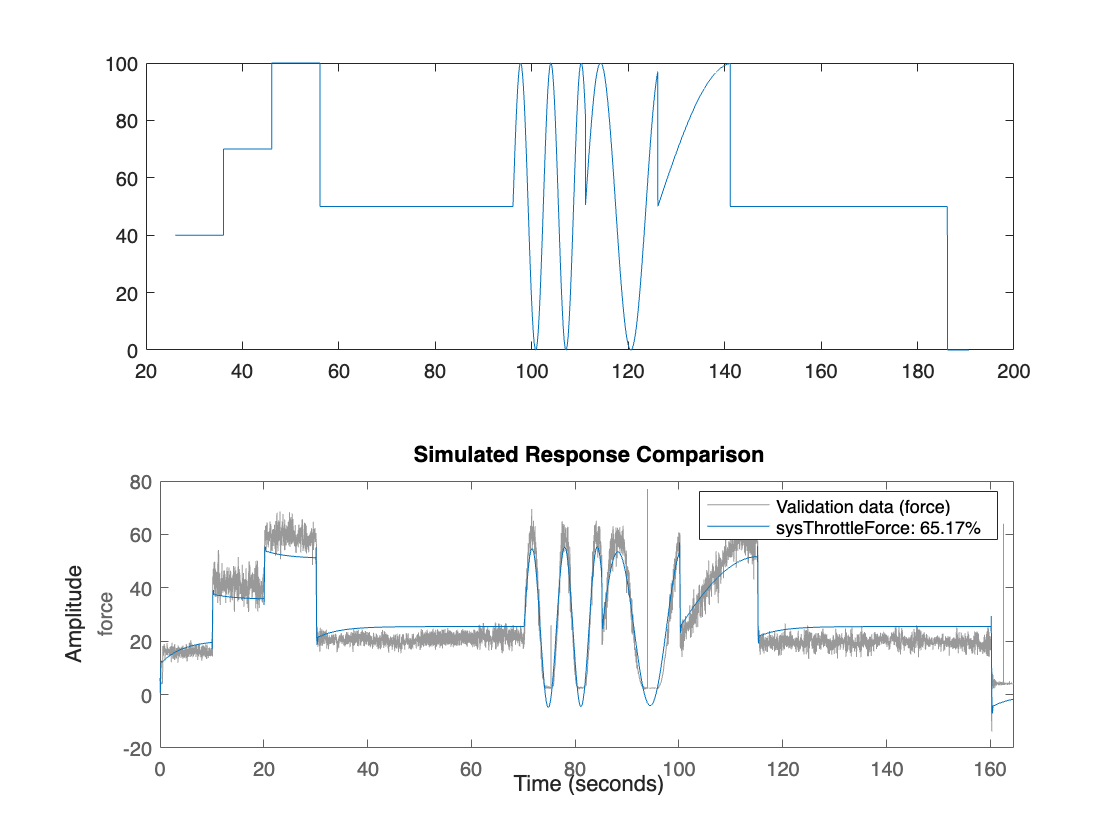


compare(throttleForceTT, sysThrottleForce)

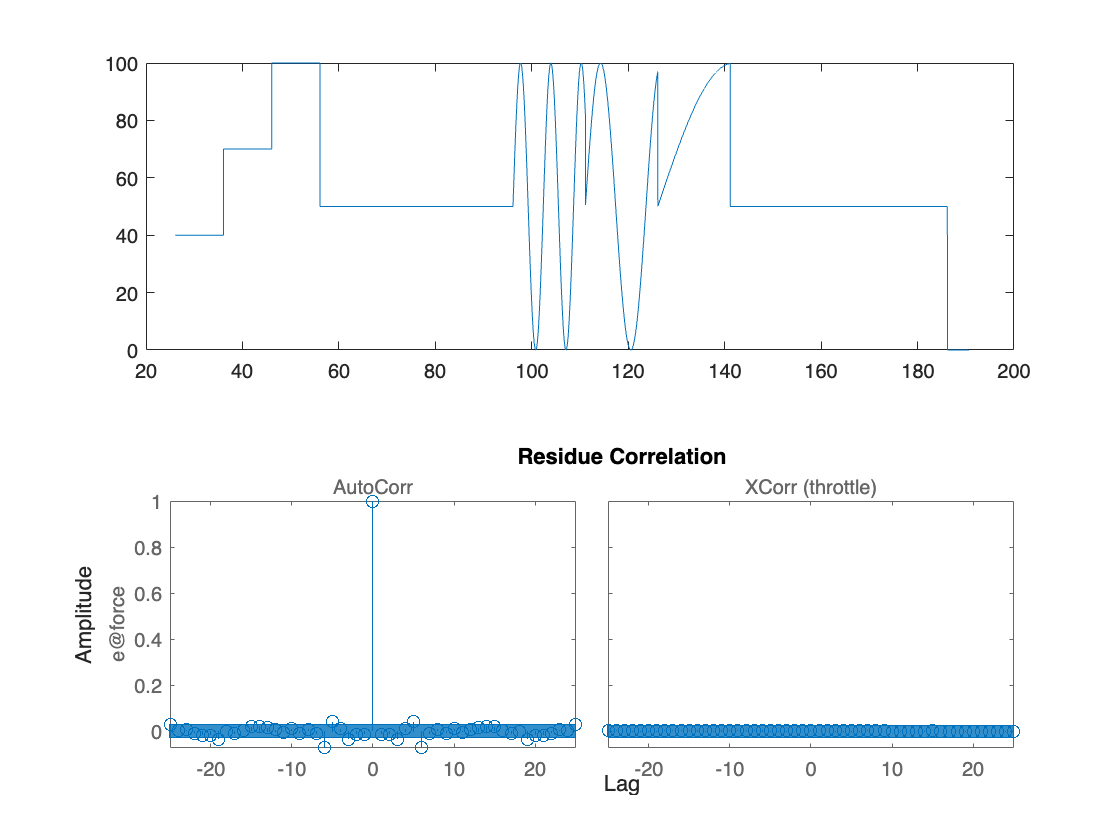


resid(sysThrottleForce, throttleForceTT)


throttleForceTT.Properties.TimeStep

ans = duration
   0.020016 sec


% compare(sys, u, y, nx)
